# **TP Projet Filtrage de Kalman **

# Migrations des tortues Luth dans l'Atlantique Nord

clc       ;
close all ;
clear all ;

## Remplissage des donnnées :

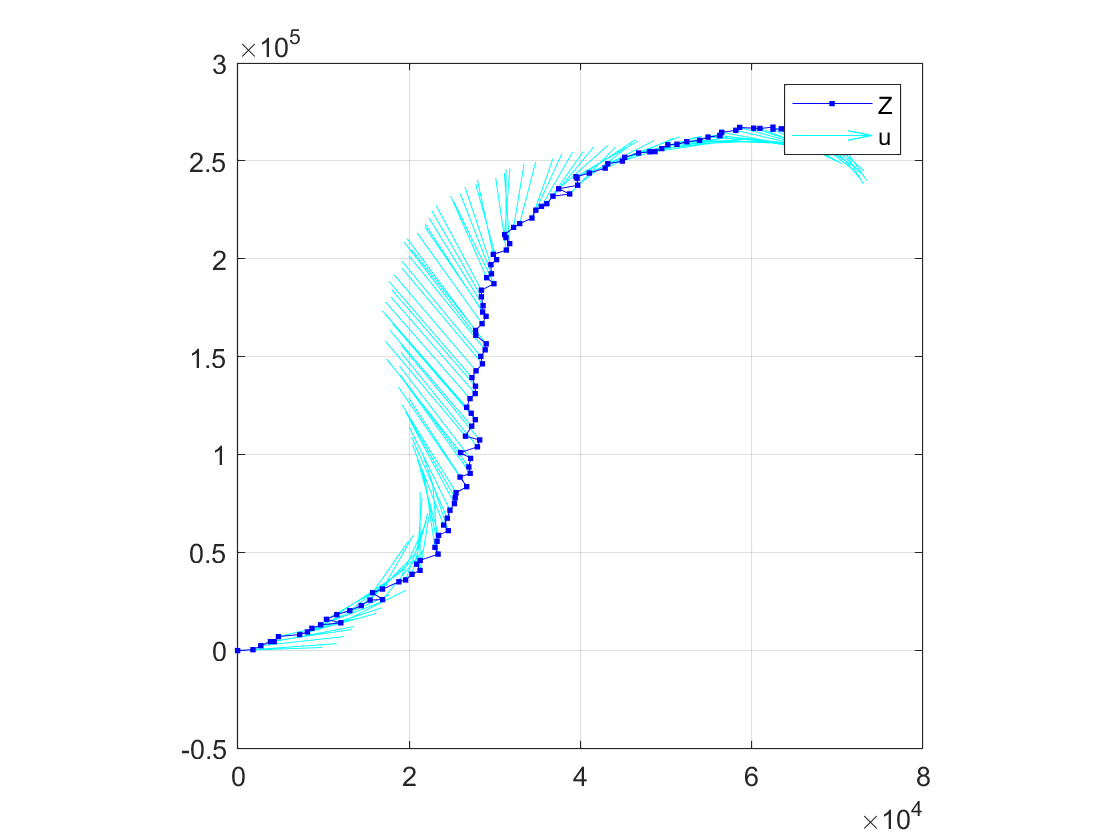

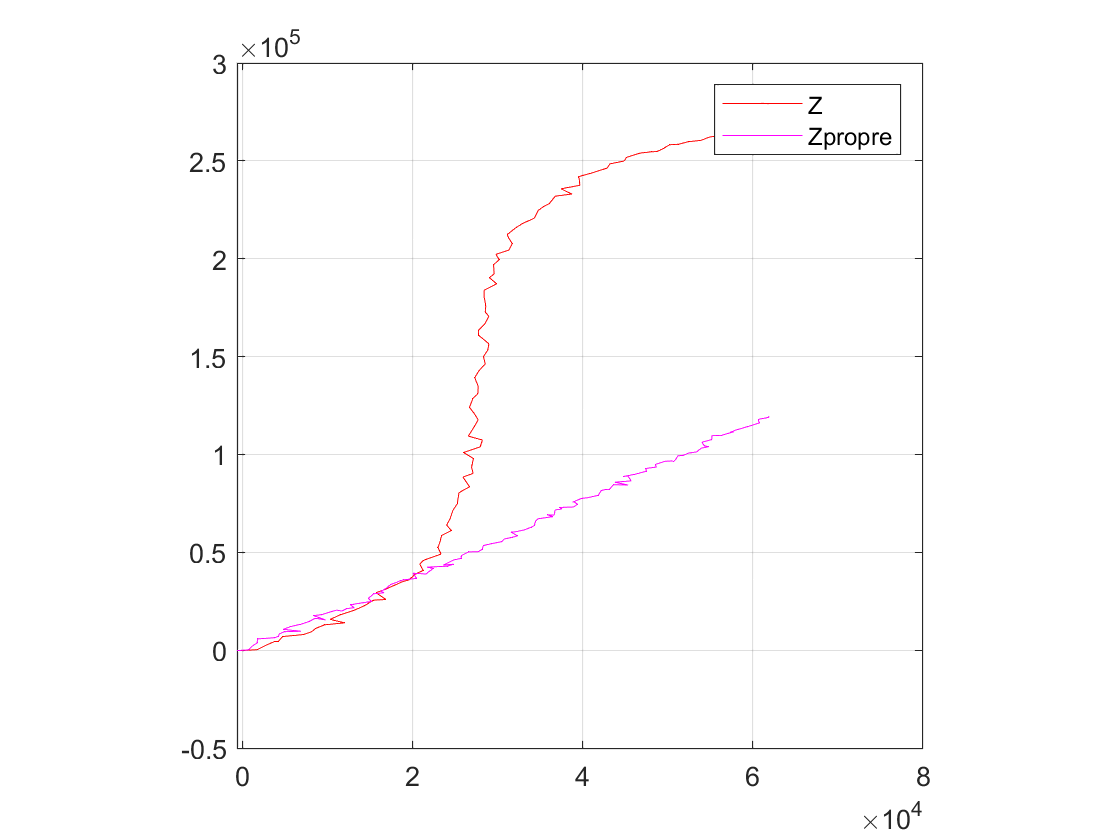


load turt8.data
[N,T,Z,u,F,G,H,mX0,PX0,Qw,Rv,X] = simulationDonnees;

% -> N : nombre d'echantillons temporels
% -> T : (1xN) vecteur des instants d'echantillonnage
% -> Z : (2xN) realisation du processus aleatoire de mesure
% -> u : (2xN) signal deterministe vecteur vitesse du courant
% -> et comme ceci est de la simulation, sont egalement accessibles
%  . F, G, H : (resp. (4x4), (4x2), (2x4)) matrices du modele
%  . mX0     : (4x1) esperance du vecteur d'etat a l'instant 0
%  . PX0     : (4x4) covariance du vecteur d'etat a l'instant 0
%  . Qw      : (4x4) covariance du bruit dynamique (suppose stationnaire)
%  . Rv      : (2x2) covariance du bruit de mesure (suppose stationnaire)
%  . X       : (4xN) realisation du processus aleatoire d'etat
% -> Z, u, X admettent AUTANT DE COLONNES QUE D'INSTANTS


%% Impacte de la modification de la covariance des bruit

%Qw = Qw / 1000 ;
%Rv = Rv * 1000 ;

Notons que modifier Q et R impacte l'optimisme sur les ellipses de confiance. Par exemple, diminuer le bruit dynamique et augmenter le bruit de mesure aura pour effet d'augmenter la taille des ellipses et écarter les intervalles d'erreurs. En revanche, modifier Q et R ici et non pas sur *simuDonnee *et plus réaliste.

## Filtre de Kalman :

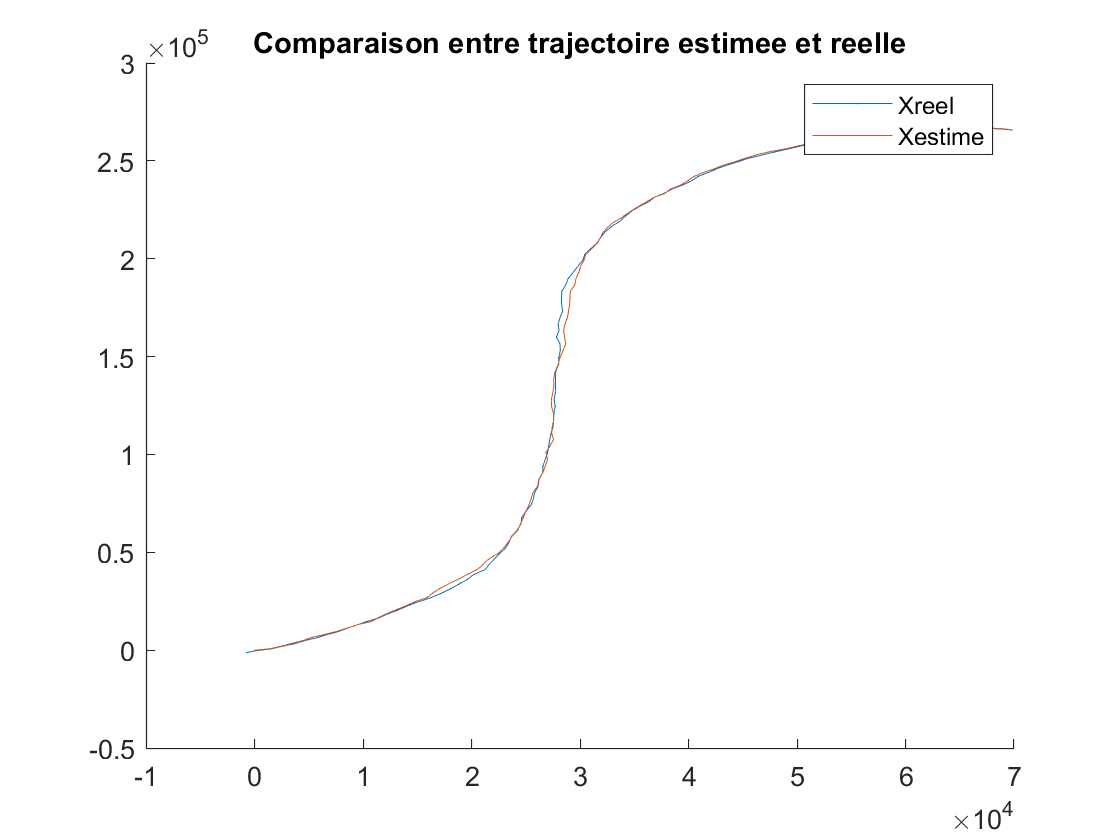

% Declarations
Ppred = cell(1, N) ; % prediction de la matrice de covariance
Pest  = cell(1, N) ; % estimation de la matrice de covariance
Xpred = cell(1, N) ; % prediction de l erreur
Xest  = cell(1, N) ; % estimation de l erreur
K     = cell(1, N) ; % gain de Kalman
Mest  = cell(1, N) ; % estimation des mesures

% Initialisation
Xpred{1} = [0; 0; 0; 0] ; % premiere cellule 4x1 a zero
Xest{1}  = mX0          ; % Eq1
Pest{1}  = PX0          ; % Eq2

% Iteration (nota: ici k represente k+1 dans les formules du cours)
for k=2:N
    % Time Update
    Xpred{k}  = F * Xest{k-1}       + G * u(:, k) ; % Eq3
    Ppred{k}  = F * Pest{k-1} * F'  + Qw          ; % Eq4
    
    % Measurement Update
    Gain{k} = Ppred{k} * H' * inv(Rv + H * Ppred{k} * H')   ; % Eq5  
    Xest{k} = Xpred{k} + Gain{k} * (Z(:, k) - H * Xpred{k}) ; % Eq6
    Pest{k} = Ppred{k} - Gain{k} * H * Ppred{k}             ; % Eq7
end

% Extraction des vecteurs
for k=1:N
   % Estimation de la postion
   vestx(k) = Xest{k}(1,1) ;
   vesty(k) = Xest{k}(2,1) ;
   
   % Matrice de covariance
   vestpx(k) = Pest{k}(1,1) ;
   vestpy(k) = Pest{k}(2,1) ;
end

%% Error Interval

xTop    = vestx + 3. * sqrt(vestpx) ;
xBottom = vestx - 3. * sqrt(vestpx) ;

yTop    = vesty + 3. * sqrt(vestpy) ;
yBottom = vesty - 3. * sqrt(vestpy) ;

%% Plot Xreel and Xestime

figure(3)
hold on
p01 = plot( X(1,:)  , X(2,:)   ) ;
p02 = plot( vestx(:), vesty(:) ) ;
legend([p01 p02], 'Xreel', 'Xestime') ;
title("Comparaison entre trajectoire estimee et reelle")
hold off

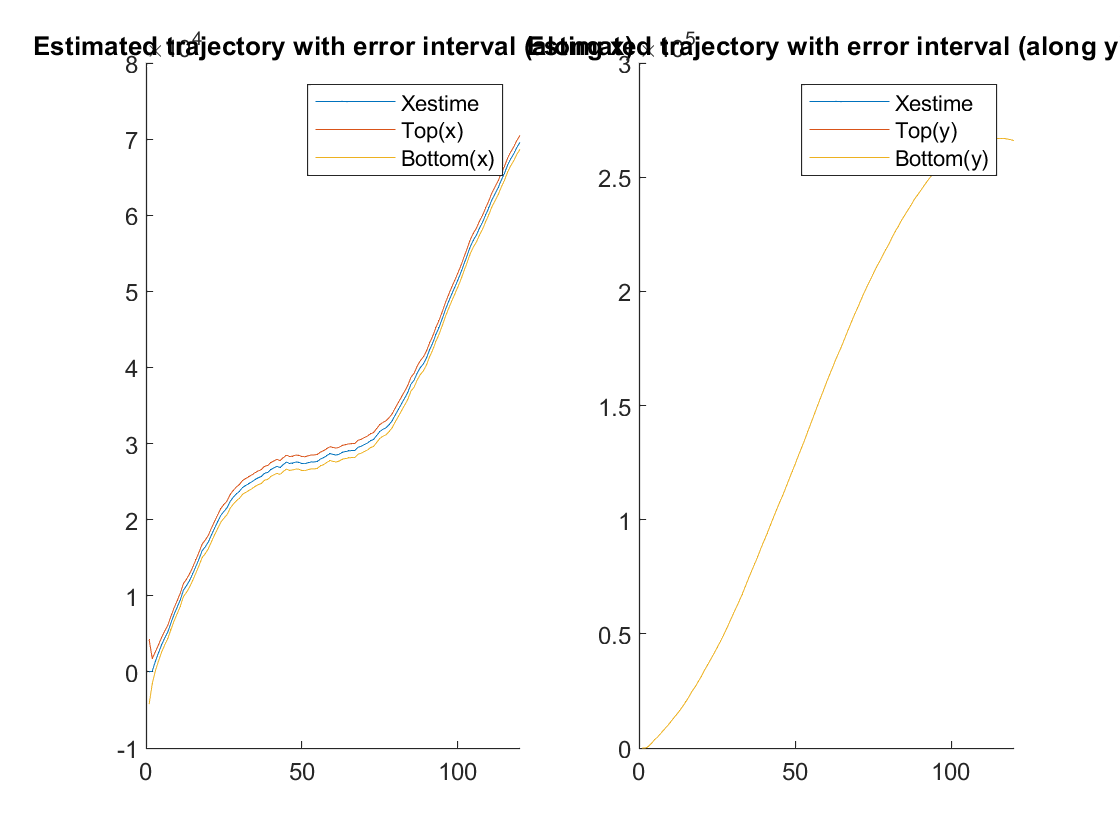


%% Plot Xestime Tops Bottoms along x and y

figure(4)
subplot(1,2,1)
    hold on
    p03 = plot( vestx(:)   );
    p04 = plot( xTop(:)    );
    p05 = plot( xBottom(:) );
    legend([p03 p04 p05],'Xestime', 'Top(x)', 'Bottom(x)');
    title("Estimated trajectory with error interval (along x)")
    hold off
subplot(1,2,2)
    hold on
    p06 = plot( vesty(:)   );
    p07 = plot( yTop(:)    );
    p08 = plot( yBottom(:) );
    legend([p06 p07 p08],'Xestime', 'Top(y)', 'Bottom(y)');
    title("Estimated trajectory with error interval (along y)")
    hold off

Il existe plus d'erreur d'estimation le long de l'axe x que le long de y. Une raison plausible serait que les erreurs sur x sont liées au mouvement discontinue de la tortue alors que ceux sur y sont liées au courant marins beaucoup plus constant.

## Affichage des Ellipses :

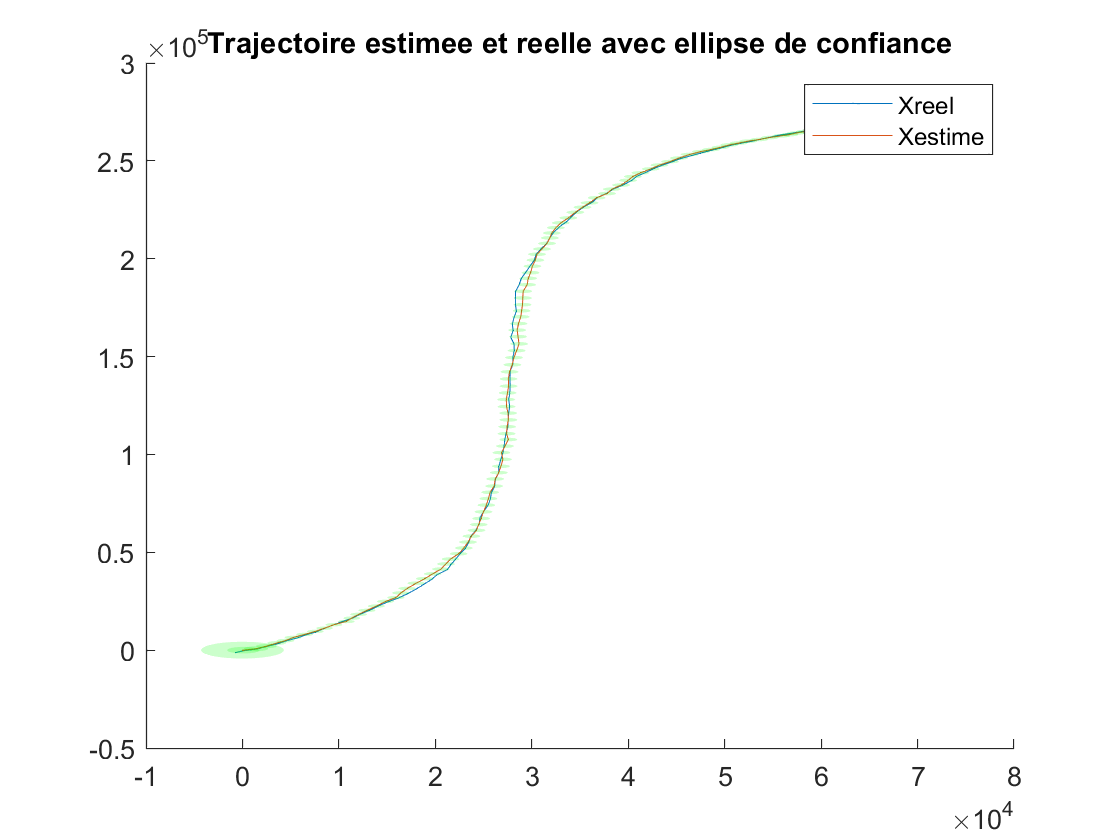

figure(5)
hold on
p09 = plot(X(1,:), X(2,:));
p10 = plot(vestx(:), vesty(:));
for k=1:N
    ellipse( Xest{k}(1:2), Pest{k}(1:2, 1:2), 'g' );
end
legend([p09 p10],'Xreel','Xestime');
title("Trajectoire estimee et reelle avec ellipse de confiance")
hold off

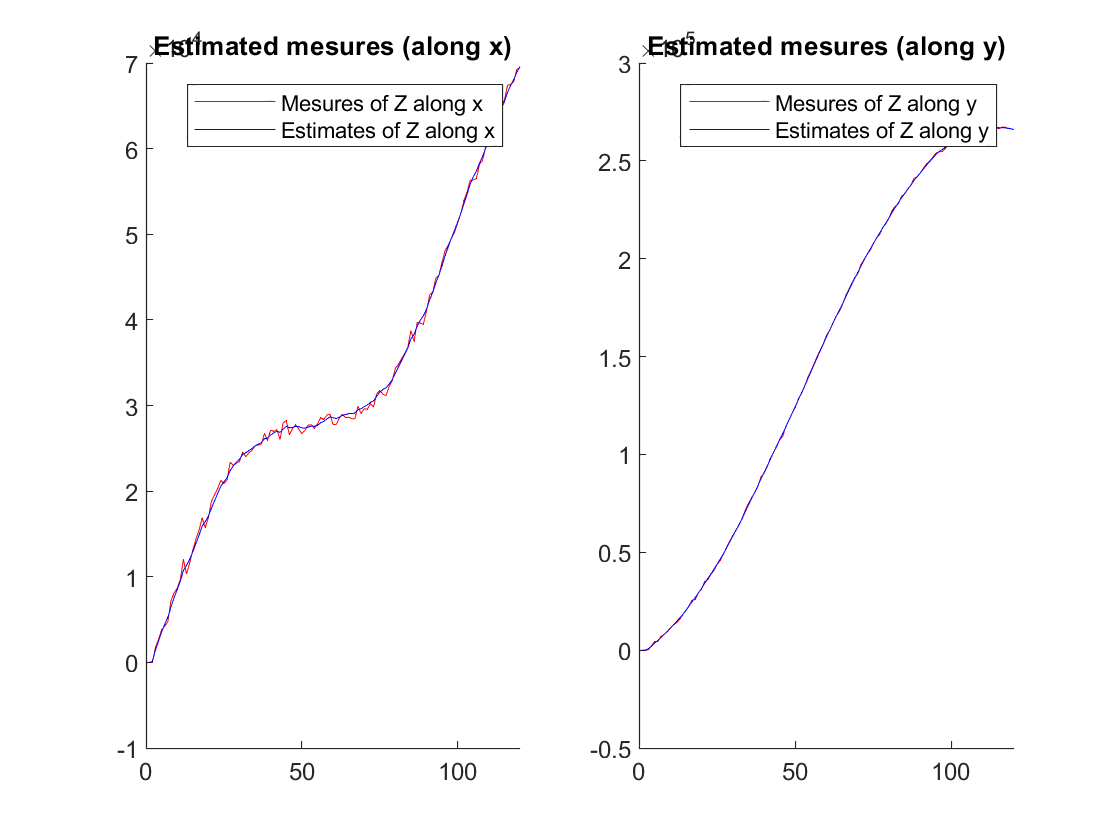


%% Innovation

% Calcul des estimations
for k=1:N
    Mest{k} = H * Xest{k};
end

% Calcul de l innovation
for k=1:N
    gamma(1, k) = Z(1, k) - Mest{k}(1, 1);
    gamma(2, k) = Z(2, k) - Mest{k}(2, 1);
    % Extration des estimations
    Mestx(1, k) = Mest{k}(1, 1);
    Mesty(1, k) = Mest{k}(2, 1);
end

% Plot des mesures estimees
figure(6)
subplot(1,2,1)
    hold on
    p11 = plot( Z(1,:)     , 'r') ;
    p12 = plot( Mestx(1,:) , 'b') ;
    legend([p11 p12],'Mesures of Z along x', 'Estimates of Z along x');
    title("Estimated mesures (along x)")
    hold off
subplot(1,2,2)
    hold on
    p13 = plot( Z(2,:)     , 'r') ;
    p14 = plot( Mesty(1,:) , 'b') ;
    legend([p13 p14],'Mesures of Z along y', 'Estimates of Z along y');
    title("Estimated mesures (along y)")
    hold off

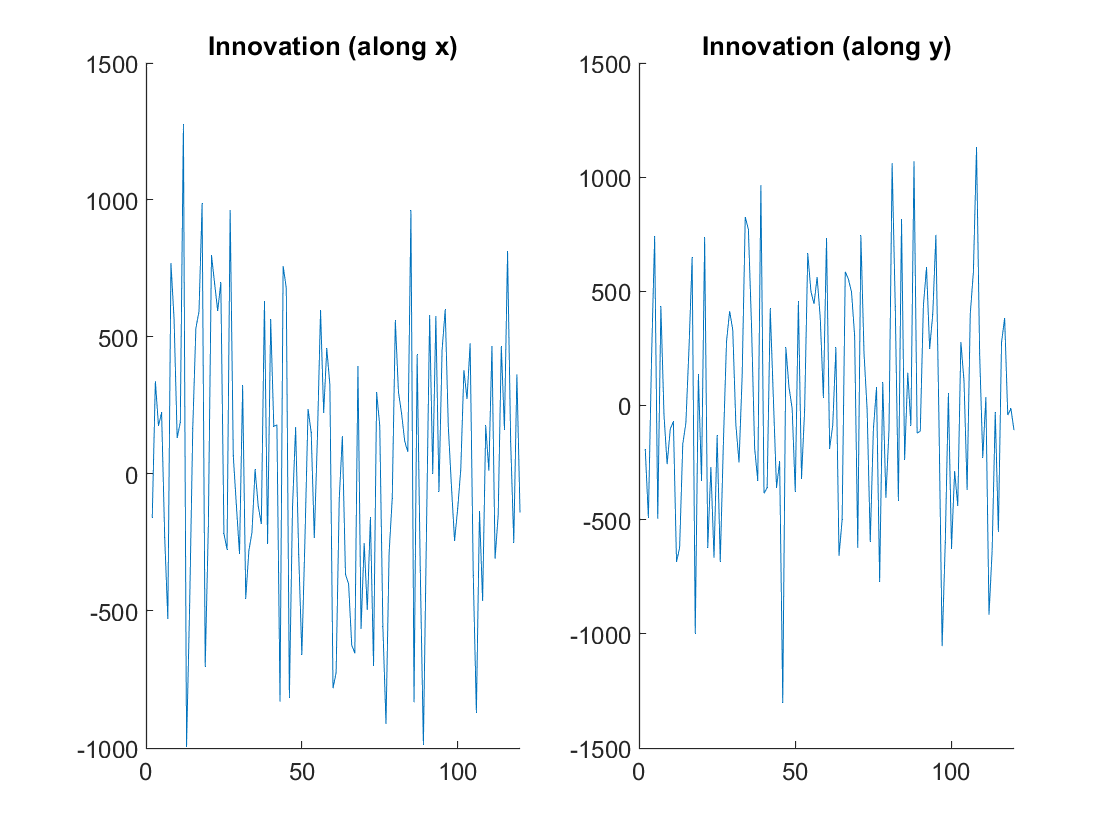


% Plot de l innovation
figure(7)
subplot(1,2,1)
    hold on
    plot( gamma(1,:) ) ;
    title("Innovation (along x)")
    hold off
subplot(1,2,2)
    hold on
    plot( gamma(2,:) ) ;
    title("Innovation (along y)")
    hold off

Nous faisons les mêmes constations que précèdement et on observe bien une plus grande amplitude d'erreur sur la position (et ici la mesure) le long de l'axe x que le long de l'axe y.